# Generate Frequency Order Map for BEV Motor Driveline

Copyright 2026 The MathWorks, Inc.

## Overview

This work flow shows how to generate frequency-order map for the motor driveline you start the vehicle from rest by applying a constant torque at the motor shaft. The torque ripples present in the motor torque give rise to a time varying radial load on the bearings that support the motor shaft. The motor torque ripple is the source of the excitation force. It may contain harmonics at various frequencies due to the fact that the AC input voltage applied to the motor is often obtained by converting the battery DC voltage. Therefore the torque harmonics depend on the switching frequency of the device used and the controller that controls the Inverter. 

## Estimate the Torque Ripple

You need to run an electrical simulation to generate the torque ripple. This example uses a FOC controlled PMSM to generate and record the starting torque that is required to start the vehicle from rest.

DLElectricalModelName = "motorDrivelineElectricalTRQControl";
simModelElec = load_system(DLElectricalModelName);

Set the battery voltage, maximum allowed current and the motor torque required to start the vehicle from rest.

batteryVoltage = simscape.Value(450,"V");
motorMAXCurrent = simscape.Value(100,"A");
startingTorque = simscape.Value(50,"N*m");
nominalMotorRPM = simscape.Value(5000,"rpm");
simulationTime = 0.5; % Electrical Simulation Duration in Sec

 Run the electrical model to generate the torque ripple when starting from rest.

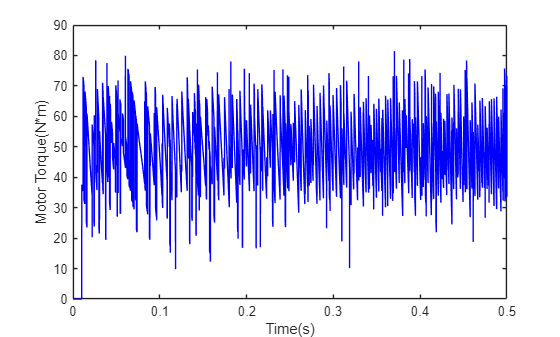

[motorTRQ,solutionTime] = simulateElectricModel(DLElectricalModelName,nominalMotorRPM,simulationTime,BatteryVoltage=batteryVoltage,...
    MaxCurrent=motorMAXCurrent,MotorTorqueSetPoint=startingTorque);

## Extend the Repeating Portion of Motor Torque

Specify the time by which you want to extend the signal.

TExtend = 5;

Specify the last `TRepeat` seconds to be used to generate the extended torque signal.

TRepeat = 0.15;

use function `extendMotorTorque` to extend the motor torque and save it into `extendedMotorTorque.mat` file.

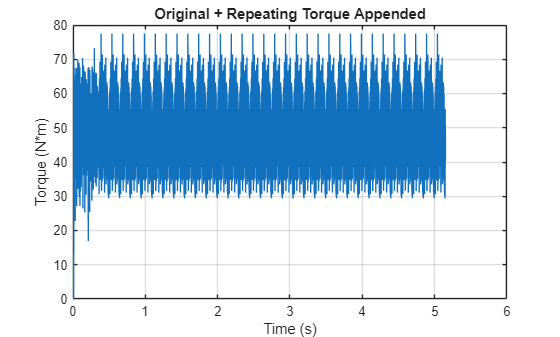

extendMotorTorque(motorTRQ,solutionTime,TExtend,TRepeat);

## Estimate Torsional Vibrations

DLMechanicalModelName = "mechanicalDLTorsionOrderMap";
simModel = load_system(DLMechanicalModelName);

Set the final drive gear ratio.

finalDrive = simscape.Value(5.75,"1");
set_param(DLMechanicalModelName +"/Flexible Driveline/Front wheel differential/Differential","cd_ratio",string(finalDrive.value));

Set bearing force measurement sample frequency.

fsMeas = 1000;

Set measurement duration for which the simulation runs.

measurementTime = 5;
set_param(simModel,"FixedStep",string(1/fsMeas),"StopTime",string(measurementTime));
set_param(DLMechanicalModelName+"/Solver Configuration","LocalSolverSampleTime",string(1/fsMeas));

Simulate vehicle start from rest to measure the excitation force at the motor bearing and motor shaft speed.

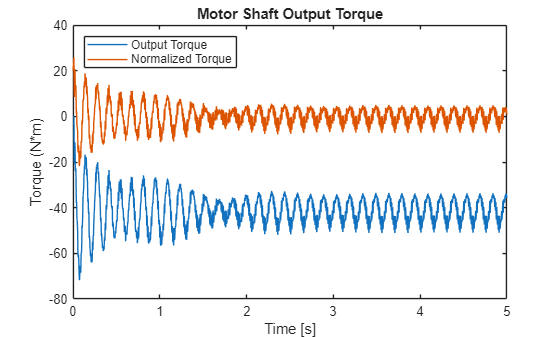

[filteredDriveTorque,RPM,bendingForce] = simulateModel(simModel,fsMeas/10,MotorShaftBending=false);

Set the total mass of rotating components of electric motor and the pinion diameter.

rotorMass = simscape.Value(20,"kg");
motorShaftPinionDia = simscape.Value(55,"mm");
vibrationForce = calculateBearingForce(filteredDriveTorque,rotorMass,motorShaftPinionDia,BendingXforceVector=bendingForce(:,1),BendingYforceVector=bendingForce(:,2));

## Generate Frequency Order map

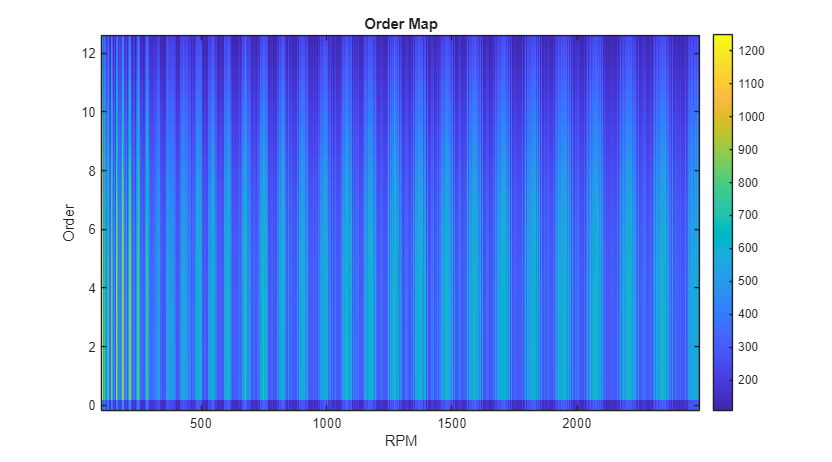

[map,orders,rpmVals] = rpmordermap(value(vibrationForce,"N"),fsMeas,RPM,20,"Amplitude","peak","OverlapPercent",80);

fig = figure("Units","pixels","Position",[100 100 900 500]);
ax = axes(fig);
imagesc(ax, rpmVals, orders, map);
axis(ax,"xy");
xlabel(ax,"RPM");
ylabel(ax,"Order");
title(ax,"Order Map");
colorbar(ax);

## Close the model

close_system(DLMechanicalModelName,0);